案例1 **高度不稳定系统 **

num = [1 50 -100 200];  % 多个右半平面零点
denum = [1 -10 100 -500 1000];  % 多个右半平面极点
P = tf(num,denum);
alphas=[2,2,2,2]

alphas =      2     2     2     2


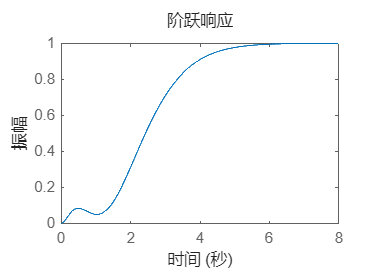

[C1,C2,T] = TwoDOFtuningFunction(num,denum,alphas);
step(T);

案例2 **病态条件系统 xx**

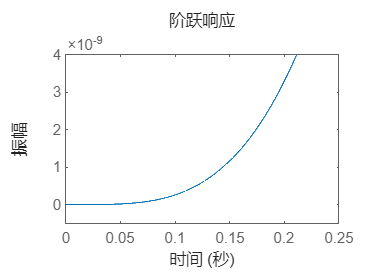

num = [1e-6 1 -1e6 1e9];  % 极端数值范围，接近奇异
denum = [1 0.001 1e6 0 0];  % 非常小的阻尼+双重积分
P = tf(num,denum);
[C1,C2,T] = TwoDOFtuningFunction(num,denum);
step(T);

案例3 **非最小相位+积分器组合**

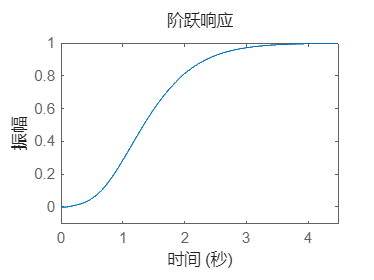

num = [1 -20 100 -1000];  % 多个不稳定零点
denum = [1 5 0 0 0];  % 三重积分器
P = tf(num,denum);
[C1,C2,T] = TwoDOFtuningFunction(num,denum);
step(T);

案例4 **高频振荡+不稳定**

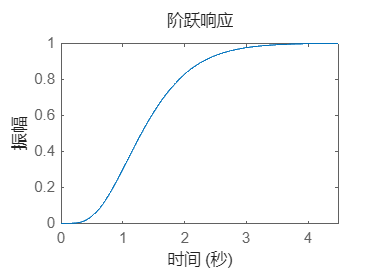

num = [1 -30 400];  % 不稳定零点
denum = [1 0.1 10000 0 0];  % 高频振荡+双重积分
P = tf(num,denum);
[C1,C2,T] = TwoDOFtuningFunction(num,denum);
step(T);

案例5 **零极点几乎相消 xx**

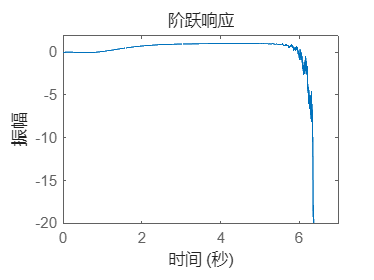

num = [1 -10.001 25.01];  % 零点接近极点
denum = [1 -10 25 0 0];  % 不稳定极点+双重积分
P = tf(num,denum);
[C1,C2,T] = TwoDOFtuningFunction(num,denum);
step(T);

案例6 **极端相对阶**

num = [1 -15 50];  % 2阶不稳定零点
denum = [1 0 0 0 0 0];  % 4重积分器（相对阶=2）
P = tf(num,denum);
[C1,C2,T] = TwoDOFtuningFunction(num,denum);

调整后的alphas: [3 3 3 3 5]


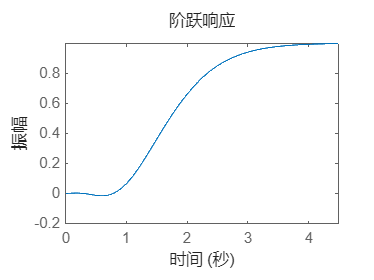

step(T);